Train ELM from human demonstration of curve tracing

clc; clear; close all;

pathname = [pwd '/datafiles/'];
file_list = dir([pathname '*.fig8.hman.mat']);

load('training_settings.mat'); 
cm = 1/100;
mm = 1/1000;
% loads curvature_threshold, ELM, 
% half_training_length, Zago filtering
% parameters, training curve


## Who's who

adele - subject1

agnes - subject2

aniket - subject3

bernardo - subject4

cuishuai - subject5

domenico - subject6

harsha_v4 - subject7

juhi - subject8

kieran - subject9

sreekanth - subject10


for j_files = 1:length(file_list)
    filename = file_list(j_files).name;
    subject_id = strsplit(filename,'.fig8.hman.mat');
    name = char(subject_id{1});
    disp(name)
    %% Defining filenames
    subject_elm_filename = strcat(subject_id{1},'.trained_elm.mat');
    subject_fig1_real_tracing = strcat(subject_id{1},'.fig1_real_tracing');
    subject_fig2_real_power_law = strcat(subject_id{1},'.fig2_real_power_law');

    %% Collecting data from log
    load( strcat(pathname,filename) );
    
    positions   = data(6:7,:);   % Positions
    velocities  = data(10:11,:); % Velocities
    time        = data(1,:)';    % Time
    
    %% Pre-processing data
    % Zago filtering
        [time_zago, speed_zago, curvature_zago, A_zago, Pt_zago,Vt_zago,At_zago] = f_powerlaw_Zago_v4 (positions, time, sampling_time, cutoff_frequency);
    % Segmenting dataset for 
        range_speed = (speed_zago > mean(speed_zago))';
        min_time = min(time_zago(range_speed)); max_time = max(time_zago(range_speed)); mid_time = (min_time + max_time)/2;
        range_speed = (speed_zago > 0)';
        %time_threshold_lower = mid_time - half_training_length; time_threshold_upper = mid_time + half_training_length;
        if j_files == 3
            time_threshold_lower = min_time+15;
        else
            time_threshold_lower = min_time;
        end
        time_threshold_upper = max_time;
        range_segmented = logical ((range_speed .* (time_zago>time_threshold_lower))); range_segmented = logical ((range_segmented .* (time_zago<time_threshold_upper)));
        
        
    % Reparameterisation to ensure training data validity
        %% Generating geometry
        GEO = f_euclidean_geometry_v3(C);
        
        %% Reparamaterisation
        SET_pstar = []; SET_err = [];
        
        Pt = Pt_zago(:,1);
        pstar = 0; % IF starting from the beginning of the dataset
        %fminbnd(@(p) GEO.dist2(p,Pt), 0, 2*pi);   %% NOTE [0 pi] is the upper lobe
        
        figure
        
        for Pt = Pt_zago    %% looping through colums
            pstar = fminbnd(@(p) GEO.dist2(p,Pt), pstar, pstar+pi/2);   %% NOTE [0 pi] is the upper lobe
            SET_pstar = [SET_pstar, pstar];
            SET_err = [SET_err, sqrt( GEO.dist2(pstar, Pt))];        
        end

        range_training = range_segmented;
        Pt_training = Pt_zago(:,range_training);
        Vt_training = Vt_zago(:,range_training);
        SET_pstar_training = SET_pstar(range_training);
    % Piecewise linear power law regression
        range_power_law = logical (range_training' .* curvature_zago>curvature_threshold);
    
        x = log10( curvature_zago(range_power_law));
        y = log10( speed_zago(range_power_law) );

        myPWLType = fittype( @(LogV0, LogKc, LogK) ...
            LogV0 + 1/3*(LogKc - LogK).*(1+sign(10.^LogK-10.^LogKc))/2, ...
            'dependent', {'LogV'},...
            'independent', {'LogK'},...
            'coefficients', {'LogV0', 'LogKc'});

        [Fitting GoF] = fit( x, y, myPWLType, ...
            'StartPoint', [log10(0.1), log10(5)],'Robust', 'LAR');

        VK_par = 10.^coeffvalues(Fitting);
        VK_CI = diff( 10.^ confint(Fitting, 0.95) )/2;
    
        
    % subject_fig1_real_tracing 
    % PAY ATTENTION TO LABELS and LEGENDS and UNITS
        h_subject_fig1_real_tracing = figure;
        
        subplot(1,2,1); 
        % ref curve (thick red), real data (thin grey), 
        % point in real data (thick1 black), C(pstar) for that point (thick2 black), 
        % line connecting the two points (thin black)
            my2Dplot(C(pi/4 * (0:7)), 'ob'); hold on;
            ref_curve = my2Dplot(C([0:0.01:2*pi]), 'k');
            ref_curve.LineWidth = 5; grid on, axis equal; % axis(.15 *[-1 1 -1 1])
            
            xlabel('x-axis [m]','Interpreter','Latex','fontsize',12), ylabel('y-axis [m]','Interpreter','Latex','fontsize',12);
            p = -pi:0.01*sampling_time:2*pi;
            [tmp1, tmp2, C_curv] = f_powerlaw_Zago_v4 (C(p), p, 0.01*sampling_time, cutoff_frequency);
            range_p = logical((p>0)' .* (C_curv>curvature_threshold ));
            high_curvature_regions = my2Dplot(C(p(range_p)),'r');
            high_curvature_regions.LineWidth = 2;
            
            real_tracing_data = my2Dplot(Pt_training,'k'); real_tracing_data.Color = [0.5 0.5 0.5];
            
            GEO = f_euclidean_geometry_v3(C);
            % Finding extrema for display purposes
            SET_err_training = SET_err(range_training);
            farthest_point_idx = find(SET_err_training==max(SET_err_training));
            farthest_point = Pt_training(:,farthest_point_idx);
            C_pstar_farthest = GEO.C(SET_pstar_training(farthest_point_idx));
            
            h_farthest_point = my2Dplot(farthest_point,'.k'); h_farthest_point.MarkerSize = 20;
            h_C_pstar_farthest = my2Dplot(C_pstar_farthest,'pb'); h_C_pstar_farthest.MarkerSize = 20;
            h_reparam_line = plot([farthest_point(1) C_pstar_farthest(1)],[farthest_point(2) C_pstar_farthest(2)],':r'); h_reparam_line.LineWidth = 3;
            text_h_farthest = text(farthest_point(1),farthest_point(2)+0.01,'$P(t)$','Interpreter','Latex','fontsize',12);
            text_h_C_pstar = text(C_pstar_farthest(1),C_pstar_farthest(2)+0.015,'$C(p^*(t))$','Interpreter','Latex','fontsize',12);

            xlim([axis_x_min axis_x_max]);
            ylim([axis_y_min axis_y_max]);
            
            hleglines = [ref_curve high_curvature_regions real_tracing_data];
            % create the legend
            hleg = legend(hleglines,'ref curve','curvature > 1 segments','demonstration data');
            hleg.Location = 'South';
            title('Demonstration data of tracing task','Interpreter','Latex','fontsize',15)
        
         subplot(1,2,2);
            h_C = plot(p(p>0), C_curv(p>0), 'k'); grid on, hold on, xlim([0,2.01*pi]);
            h_C.LineWidth = 5;
            h_curvature_thresholded = plot(p(range_p), C_curv(range_p), '.r');
            h_curvature_thresholded.LineWidth = 2;
            xlabel('$p$ [rad]','Interpreter','Latex','fontsize',12), ylabel('curvature [1/m]','Interpreter','Latex','fontsize',12)
            set(gca, 'XTick', pi/4 * (0:8), ...
            'XTickLabel', {'0', '', '\pi/2', '', '\pi', '', '3\pi/2', '', '2\pi'});
            hleglines = [h_C h_curvature_thresholded];
            % create the legend
            hleg = legend(hleglines,'ref curve curvature','curvature > 1 segments');
            hleg.Location = 'SouthOutside';
            title('Curvature vs parameter $p$','Interpreter','Latex','fontsize',15)
%         % pstar progression
%         plot(time_zago(range_training),SET_pstar_training);
        %savefig(h_subject_fig1_real_tracing,strcat(pathname, char(subject_fig1_real_tracing),'.fig'));
        exportgraphics(h_subject_fig1_real_tracing,strcat(pathname, char(subject_fig1_real_tracing),'.pdf'),'BackgroundColor','none');
        
    % subject_fig2_real_power_law
    % PAY ATTENTION TO LABELS and LEGENDS and UNITS
        h_subject_fig2_real_power_law = figure;

        subplot(2,2,1);
        % Zago filtered speed
            plot(time_zago(range_power_law), speed_zago(range_power_law)); grid on, hold on
            ylabel(' speed [m/s]'); xlabel('time [s]'); %xlim([3 80]) %xlim([1 30])
            title('Speed recorded by subject');

        subplot(2,2,3);
        % Zago filtered curvature
            plot(time_zago(range_power_law), curvature_zago(range_power_law)); %ylim([0 100])
            ylabel(' curvature [1/m]'); xlabel('time [s]'); %xlim([3 80]) %ylim ([0 50]), 
            title('Curvature traced by subject')
        
        subplot(2,2,[2 4]);
        % Log speed vs Log curvature plot, Real data (grey), 
            loglog(curvature_zago(range_power_law), speed_zago(range_power_law), '.', 'Color', [.7 .7 .7]); grid on; hold on;
            loglog (curvature_zago(range_power_law), 10.^Fitting(log10(curvature_zago(range_power_law))), '.r');       
            loglog(VK_par(2), VK_par(1), 'ko')
            ylabel('speed (m/s)'), xlabel('curvature [1/m]'),xlim([curvature_threshold 100]); %legend('data','-2/3');
            title('PPL from real tracing data');
        
        %savefig(h_subject_fig2_real_power_law,strcat(pathname, char(subject_fig2_real_power_law),'.fig'));
        exportgraphics(h_subject_fig2_real_power_law,strcat(pathname, char(subject_fig2_real_power_law),'.pdf'),'BackgroundColor','none');
    
    %% Preparing observations for ELM
        max_C_ss = 50;
        max_mu = 50;
        
        %% Moving frame geometry
            Z_BUILDER = @(Pt, pstar, GEO) ...
            [ [0 1]*inv( GEO.MF(pstar) ) * (Pt - GEO.C(pstar));
            [0 1] * inv( GEO.MF(pstar) ) * GEO.C_ss(pstar) / max_C_ss;
            0.1*mod(pstar,2*pi);
            ];
        
        Z_all = [];
        Y_all = [];
        Pt_all = [];
        pstar_all = [];
        for j=1:length(Pt_training)-1
            Pt = Pt_training(:,j);
            Vt = Vt_training(:,j); 
            pstar = SET_pstar_training(j);
            pstar = mod(pstar,2*pi);
            Z_all(:,j) = Z_BUILDER( Pt , pstar, GEO);
            Y_all(:,j) = inv(GEO.MF(pstar)) * Vt;
            Pt_all(:,j) = Pt;
            pstar_all(:,j) = pstar;
        end
        
    %% Training ELM
    

#### Clubbing washout and training

        Ndata = length(Z_all);
        
        range_train = 1 : Ndata;%round(Ndata*2/3);             %% training range
        %range_test = round(Ndata*2/3)+1 : Ndata - 1;   %% testing range, up to N-1
        
        range = range_train;    % range for training 
        Z_train = Z_all (:, range);
        Y_train = [Y_all(:, range)]; %% *** NOTE range + 1 ***
        
        
%         range = range_test;     % range for testing
%         Z_test = Z_all (:, range);
%         Y_test = [Y_all(:, range)]; %% *** NOTE range + 1 ***
%         
        %figure, plot(Z_test','b'),hold on, plot(Y_test','r'),legend('Z (blue)','Y (red)');title('Z-test and Y-test')
        

#### Storing random starting points from training set

        % generate the four random indices
        randIdcs = randperm(length(Z_train),no_samples);
        % initialize R to be the four numbers of A
        Pt_samples = Pt_all(:,randIdcs);
        pstar_samples = pstar_all(:,randIdcs);

### ELM Training

    ELM.Nx = 100;
    ELM.Nz = min(size(Z_train));
    ELM.Ny = min(size(Y_train));
    rng('default');
    ELM.C = (2.0 * rand(ELM.Nx, ELM.Nz) - 1.0);
    zeta_bias = 0;
    % not ones(N, d) as was given in the original code
    ELM.zeta = zeta_bias * ones(ELM.Nx, 1);
    % Spectral radius - the closer to 1 the better, can even increase beyond 1 making the system unstable, although it might still enable better learning (not sure why)
    rho_A = 0.95;
    ELM.A = 0; % * A * rho_A; % ELM
    c = 1;
    ELM.Dyn = @(Xt, Zt)radbas(ELM.A * Xt + c * ELM.C * Zt + ELM.zeta);

    % Training phase
    N_train = length(Z_train);
    mean_Z = mean(Z_train, 2);
    std_Z = std(Z_train, [], 2);
    mean_Y = mean(Y_train, 2);
    std_Y = std(Y_train, [], 2);
    Z_train_norm = (Z_train - mean_Z) ./ std_Z;
    Y_train_norm = (Y_train - mean_Y) ./ std_Y;
    
%     rng default % For reproducibility
%     opts = optimoptions(@fmincon,'Algorithm','interior-point');
%     problem = createOptimProblem('fmincon','objective',...
%         @(arg_goal)min_lambda_C(arg_goal, ELM, N_train, Z_train_norm, Y_train_norm, ...
%             pstar_all(range_train), Pt_all(:,range_train), GEO, Z_BUILDER, sampling_time, mean_Z, std_Z, mean_Y, std_Y),'x0',[0.1, 10],'lb',[0.01, 1e-5],'ub',[10, 500],'options',opts);
%     ms = MultiStart('Display', 'iter','StartPointsToRun',"bounds-ineqs", "UseParallel",true);
%     [x_res,f] = run(ms,problem,20)
    
    options = optimoptions('fmincon', 'Display', 'iter');
     x_res = fmincon(@(arg_goal)min_lambda_C(arg_goal, ELM, N_train, Z_train_norm, Y_train_norm, ...
            pstar_all(range_train), Pt_all(:,range_train), GEO, Z_BUILDER, sampling_time, mean_Z, std_Z, mean_Y, std_Y), [0.1, 10], ...
            [], [], [], [], [0.01, 1e-5], [10, 500], [], options);
        ridgeLambda = x_res(2);
        c = x_res(1);
        ELM.C =  ELM.C * c;
    c_opt = c;
    
    disp(ridgeLambda);disp(c);
    % Xt contains the last value of the washout set
    j = 1;
    Xt = zeros(ELM.Nx, 1);
    X_train = zeros(ELM.Nx, N_train);
    ELM.Dyn = @(Xt, Zt)radbas(ELM.A * Xt + ELM.C * Zt + ELM.zeta);
    for Zt = Z_train_norm
        Xt = ELM.Dyn(Xt, Zt);
        X_train(:, j) = Xt;
        j = j + 1;
    end
    figure;plot(X_train(1, :));
    
    ELM.W4 = (X_train * X_train' + ridgeLambda * eye(ELM.Nx)) \ (X_train * Y_train_norm');
    ELM.b = mean(Y_train_norm, 2) - ELM.W4' * mean(X_train, 2);
    % definition of 'Eval' function
    ELM.Eval = @(Xt) ELM.W4' * Xt + ELM.b;
    
    figure;
    plot(ELM.W4);
    grid on;
    title('ELM weights');
    
    Y_train_hat = ELM.Eval(X_train); %Y_train_hat = ELM.W4' * X_train(:, :) + ELM.b;
        figure;
    plot(Y_train_hat(1, :)', 'r');
    hold on;
    grid on;
    plot(Y_train_hat(2, :)', 'b');
    hold on;
    grid on;
    plot(Y_train_norm(1, :)', 'g');
    hold on;
    grid on;
    plot(Y_train_norm(2, :)', 'k');
    title('Training Pt components - 1-step lookahead');

    figure;
    plot(abs(Y_train_hat(1,:) - Y_train_norm(1,:)));
    hold on;
    plot(abs(Y_train_hat(2,:) - Y_train_norm(2,:)));
    title('Training error');
    
%     % Testing phase - 1-step look ahead
%     N_test = length(range_test);
%     % to keep track of Xt
%     X_test = zeros(ELM.Nx, N_test);
%     Y_test_1step = zeros(ELM.Ny, N_test);
%     
%     % Xt contains the last value of the training set
%     Z_test_norm = (Z_test - mean_Z) ./ std_Z;
%     Y_test_norm = (Y_test - mean_Y) ./ std_Y;
%     j = 1;
%     for Zt = Z_test_norm
%         Xt = ELM.Dyn(Xt, Zt);
%         Yt = ELM.Eval(Xt);
%         % just logging
%         X_test(:, j) = Xt;
%         % just logging
%         Y_test_1step(:, j) = Yt;
%         j = j + 1;
%     end
%     
%     figure;
%     plot(Y_test_1step(1, :)', 'r');
%     hold on;
%     grid on;
%     plot(Y_test_1step(2, :)', 'b');
%     hold on;
%     grid on;
%     plot(Y_test_norm(1, :)', 'g');
%     hold on;
%     grid on;
%     plot(Y_test_norm(2, :)', 'k');
%     title('Pt components - 1-step lookahead');
%     
    Xt = X_train(:, end);     
    X_train_end = X_train(:, end);
%     
%     Z_test_len = length(Z_test_norm);
        

### Defining ELM ID for saving this training

subject1


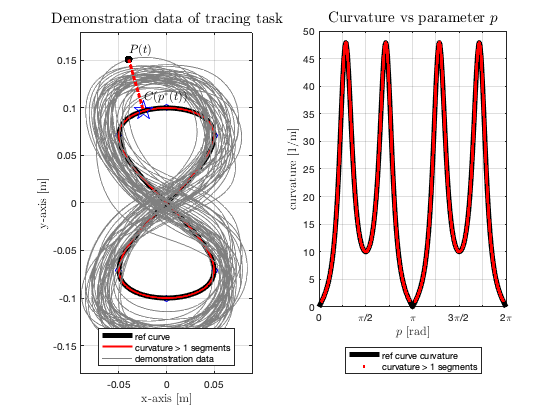

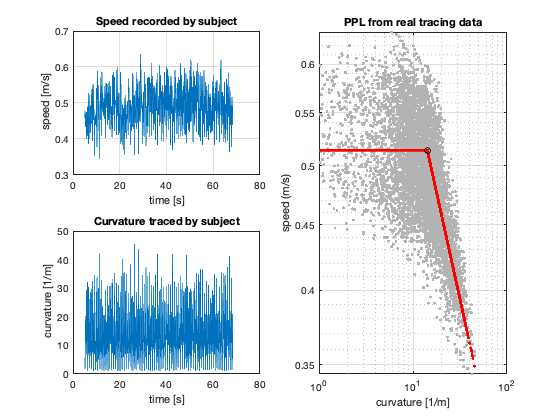

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    7.843510e-01    0.000e+00    8.589e-04
    1       6    7.843504e-01    0.000e+00    8.589e-04    5.246e-03
    2       9    7.843457e-01    0.000e+00    8.591e-04    4.003e-02
    3      12    7.843365e-01    0.000e+00    8.595e-04    7.442e-02
    4      15    7.843097e-01    0.000e+00    8.608e-04    2.150e-01
    5      18    7.842788e-01    0.000e+00    7.715e-04    4.176e-01
    6      21    7.842403e-01    0.000e+00    7.733e-04    3.012e-01
    7      24    7.836987e-01    0.000e+00    8.050e-04    3.891e+00
    8      27    7.833660e-01    0.000e+00    8.190e-04    2.484e+00
    9      31    7.832265e-01    0.000e+00    8.251e-04    1.284e+00
   10      34    7.832238e-01    0.000e+00    8.250e-04    1.348e-02
   11      37    7.832200e-01    0.000e+00    8.252e-04    6.189e-03
   12      40    7.831978e-01    0.000e+00    8

    2.0037

    5.5460



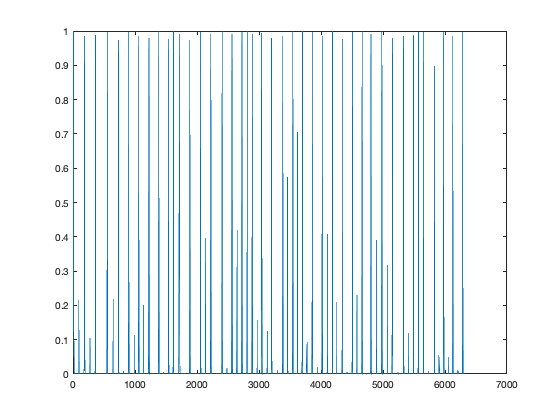

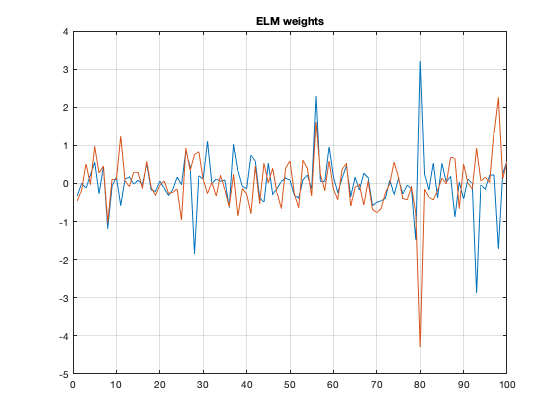

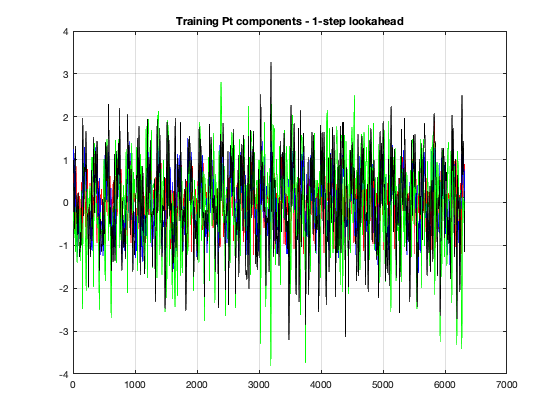

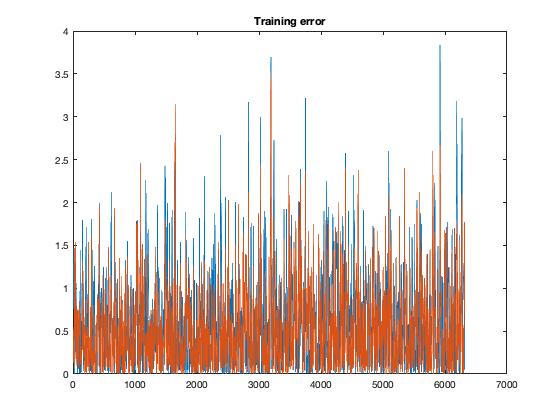

        Pt_train = Pt_training;
        Vt_train = Vt_training;
        Pt_end = Pt_train(:,end);
        
        VK_real = VK_par;
        VK_CI_real = VK_CI;
    %% Saving the ELM, real power-law characteristics
    save(strcat(pathname, char(subject_elm_filename)));
    end